low_diff=[];
high_diff=[];




% lft 1: fix peak, 0 channels pre-peak, 148 channels post-peak;
% lft 2: fix peak, 20 channels pre-peak, 148 channels post-peak;
i=1192

i =         1192


j=2619

j =         2619


nsPerPoint=25/256;
low_lft_histogram=squeeze(FLPdata_lifetimes(i,1,:));

Unrecognized function or variable 'FLPdata_lifetimes'.

high_lft_histogram=squeeze(FLPdata_lifetimes(j,1,:));

lifetimes=low_lft_histogram;

lft_points=[1:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

low_lft_1=EmpTauTrunc;

lft_points=[-19:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point-20):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

low_lft_2=EmpTauTrunc;

lifetimes=high_lft_histogram;

lft_points=[1:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

high_lft_1=EmpTauTrunc;

lft_points=[-19:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point-20):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

high_lft_2=EmpTauTrunc;

low_lft_1
high_lft_1
low_diff=low_lft_1-low_lft_2
high_diff=high_lft_1-high_lft_2

low_diff-high_diff


low_lft_peak=find(low_lft_histogram==max(low_lft_histogram))
high_lft_peak=find(high_lft_histogram==max(high_lft_histogram))

figure
semilogy(low_lft_histogram)
hold on
semilogy(high_lft_histogram)
legend('low lft','high lft')
title([num2str(low_lft_peak),',',num2str(high_lft_peak)])


low_lft_histogram_norm=low_lft_histogram/max(low_lft_histogram);
high_lft_histogram_norm=high_lft_histogram/max(high_lft_histogram);
figure
semilogy(low_lft_histogram_norm)
hold on
semilogy(high_lft_histogram_norm)
legend('low lft','high lft')

figure
semilogy(low_lft_histogram_norm(38:48))
hold on
semilogy(high_lft_histogram_norm(38:48))
legend('low lft','high lft')


% lft 1: fix peak, 0 channels pre-peak, 148 channels post-peak;
% lft 2: fix peak, 20 channels pre-peak, 148 channels post-peak;
i=2499

i =         2499


j=2796

j =         2796


nsPerPoint=25/256;
low_lft_histogram=squeeze(FLPdata_lifetimes(i,1,:));

Unrecognized function or variable 'FLPdata_lifetimes'.

high_lft_histogram=squeeze(FLPdata_lifetimes(j,1,:));

lifetimes=low_lft_histogram;

lft_points=[1:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

low_lft_1=EmpTauTrunc;

lft_points=[-19:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point-20):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

low_lft_2=EmpTauTrunc;

lifetimes=high_lft_histogram;

lft_points=[1:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

high_lft_1=EmpTauTrunc;

lft_points=[-19:1:149]*nsPerPoint;
peak_point = 42;
empirical_lifetimes=lifetimes((peak_point-20):(peak_point+148));
EmpTauTrunc = sum(empirical_lifetimes.*lft_points')/sum(empirical_lifetimes);

high_lft_2=EmpTauTrunc;

low_lft_1
high_lft_1
low_diff=low_lft_1-low_lft_2
high_diff=high_lft_1-high_lft_2

low_diff-high_diff


low_lft_peak=find(low_lft_histogram==max(low_lft_histogram))
high_lft_peak=find(high_lft_histogram==max(high_lft_histogram))

figure
semilogy(low_lft_histogram)
hold on
semilogy(high_lft_histogram)
legend('low lft','high lft')
title([num2str(low_lft_peak),',',num2str(high_lft_peak)])


low_lft_histogram_norm=low_lft_histogram/max(low_lft_histogram);
high_lft_histogram_norm=high_lft_histogram/max(high_lft_histogram);
figure
semilogy(low_lft_histogram_norm)
hold on
semilogy(high_lft_histogram_norm)
legend('low lft','high lft')

figure
semilogy(low_lft_histogram_norm(38:48))
hold on
semilogy(high_lft_histogram_norm(38:48))
legend('low lft','high lft')




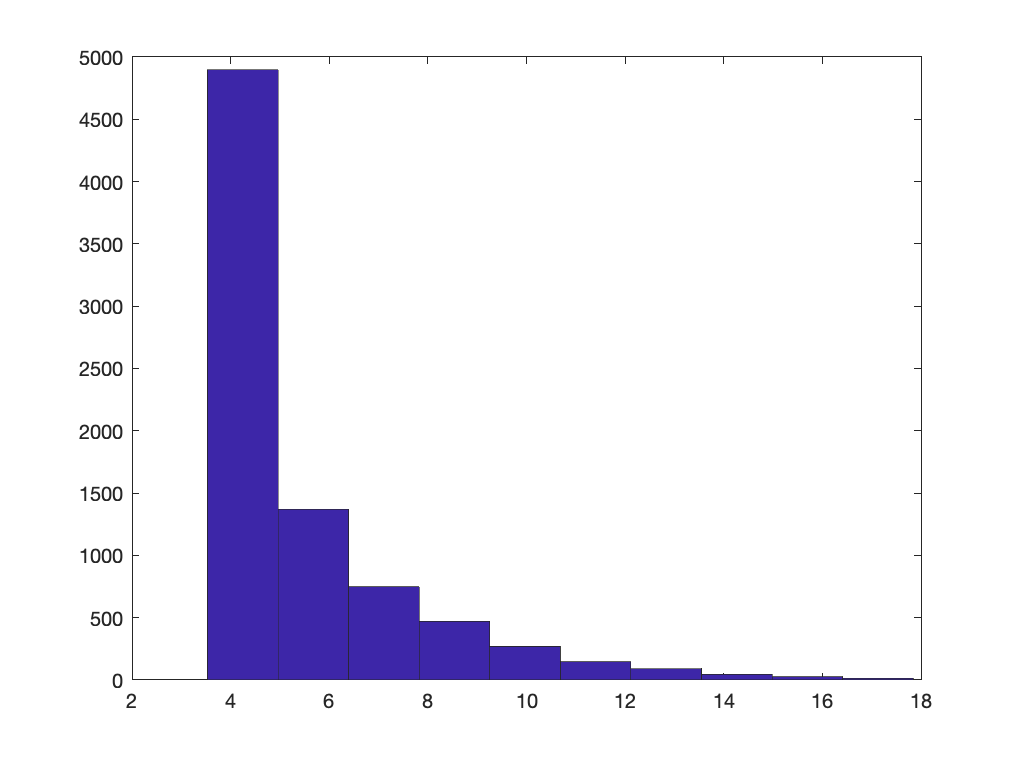

peak =     37




TP_s=[1000 5000 10000 50000 100000 500000 1000000];
tau1=2.706;
p1=0.8;
tau2=0.2613;
p2=0.2;
peaks=[];
xsim=linspace(0,25,256);

for i=1
    TP=TP_s(i);
    PopulationName=num2str(TP);
%     GenPop256_FLP(TP, p1, p2, tau1, tau2, PopulationName);
    load(PopulationName)
    Sample=Population;
    SampleC=zeros(1, length(Sample));
    figure
    hist(Population)
    
    for i=1:length(Sample)
        a=find(histc(rand(),[cumsum(Gaussian_y(:))]))-37;
        SampleC(i)=Sample(i)+a*(25/256);
        if SampleC(i)>25
            SampleC(i)=SampleC(i)-25;
        else if SampleC(i)<0
                SampleC(i)=SampleC(i)+25;
        end
        end
    end
    [n, xout]=hist(SampleC, xsim);
    peak=find(n==max(n))
    peaks=[peaks peak];
end


peaks

peaks =     37


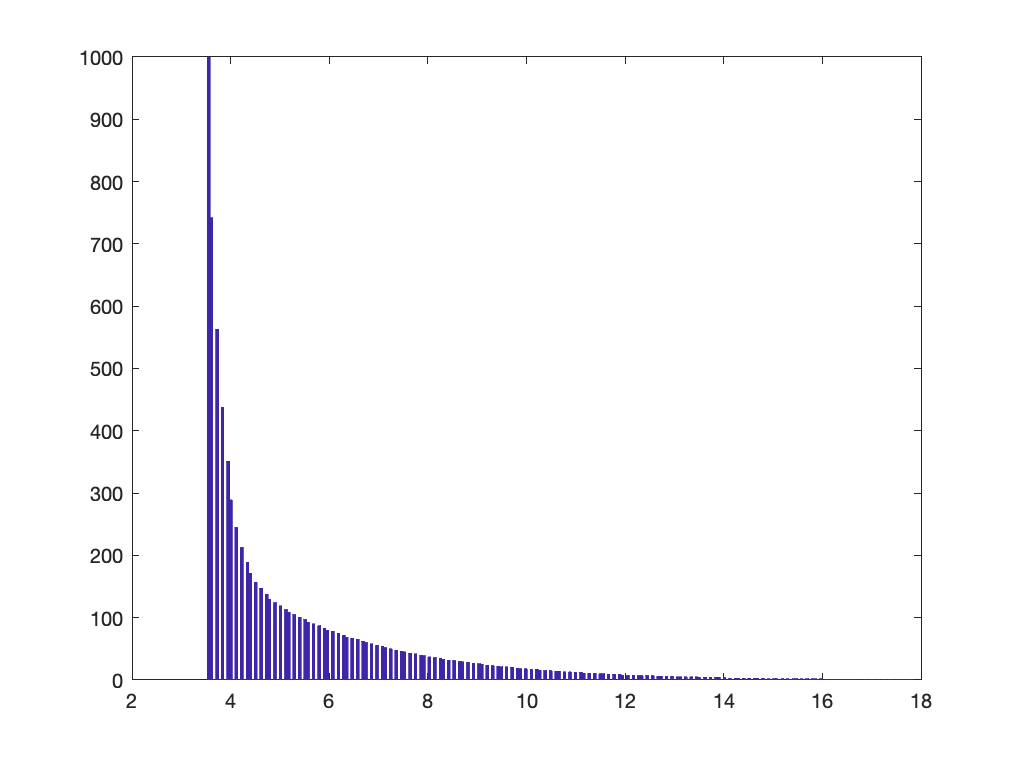

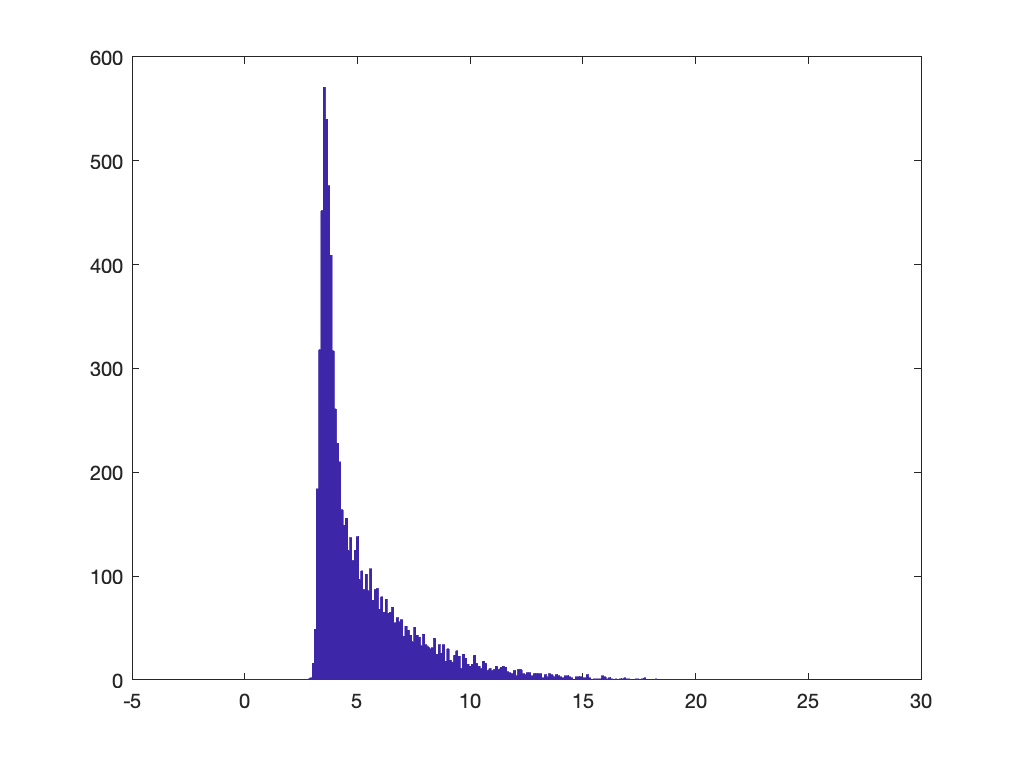

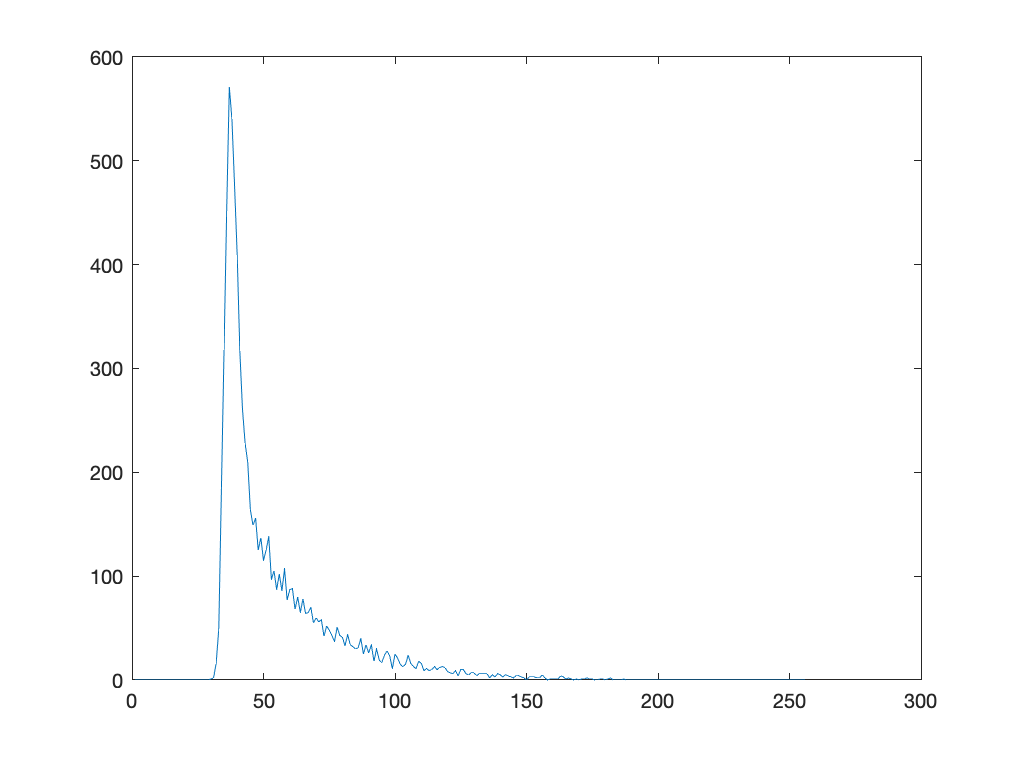

peak =     37



TP_s=[1000 2000 3000 5000 10000 50000 100000 500000 1000000 5000000];
tau1=2.706;
p1=0.8;
tau2=0.2613;
p2=0.2;


for i=1
    TP=TP_s(i);
    PopulationName=num2str(TP);
%     GenPop256_FLP(TP, p1, p2, tau1, tau2, PopulationName);
    load(PopulationName)
    Sample=Population;
    SampleC=zeros(1, length(Sample));
    figure
    hist(Population,256)
    
    
    for i=1:length(Sample)
        a=find(histc(rand(),[cumsum(Gaussian_y(:))]))-37;
        SampleC(i)=Sample(i)+a*(25/256);
        if SampleC(i)>25
            SampleC(i)=SampleC(i)-25;
        else if SampleC(i)<0
                SampleC(i)=SampleC(i)+25;
        end
        end
    end
    figure
    hist(SampleC,xsim)
    
    [n, xout]=hist(SampleC, xsim);
    
    figure
    plot(n)
    peak=find(n==max(n))
    peaks=[peaks peak];
end


peaks

peaks =     37    37


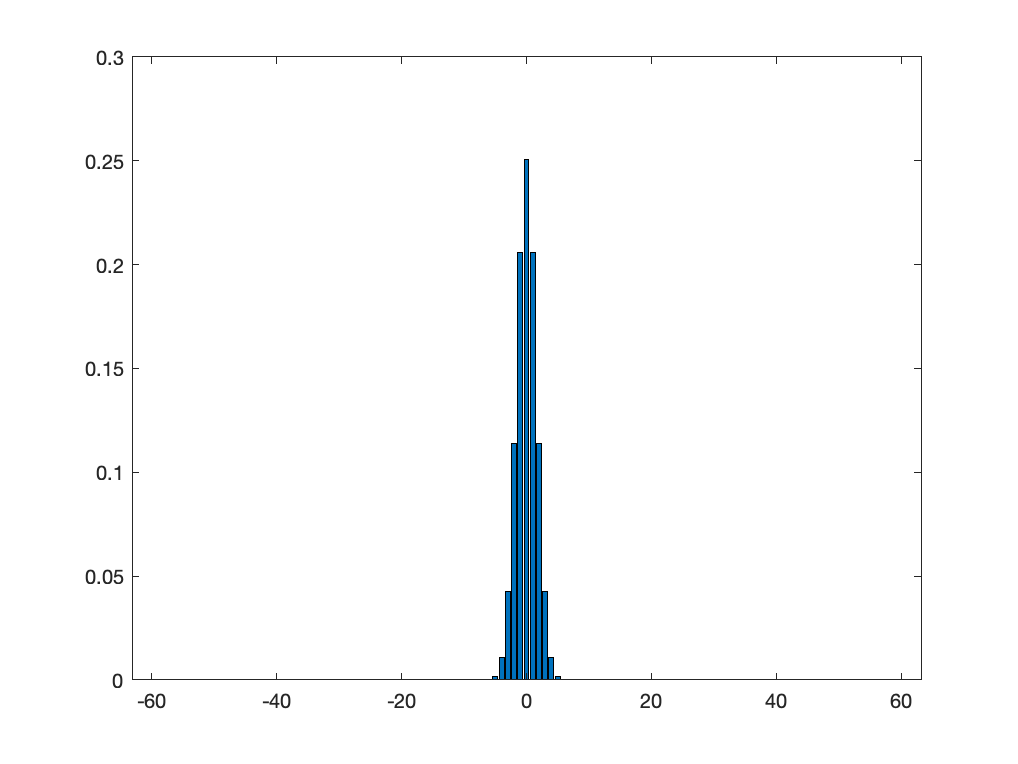

width=0.1554;
miu=0;
% x=linspace(-12.5,12.5,256);
x_i=-62:1:62;
x=x_i*(25/256);

Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
bar(x_i,Gaussian_y)

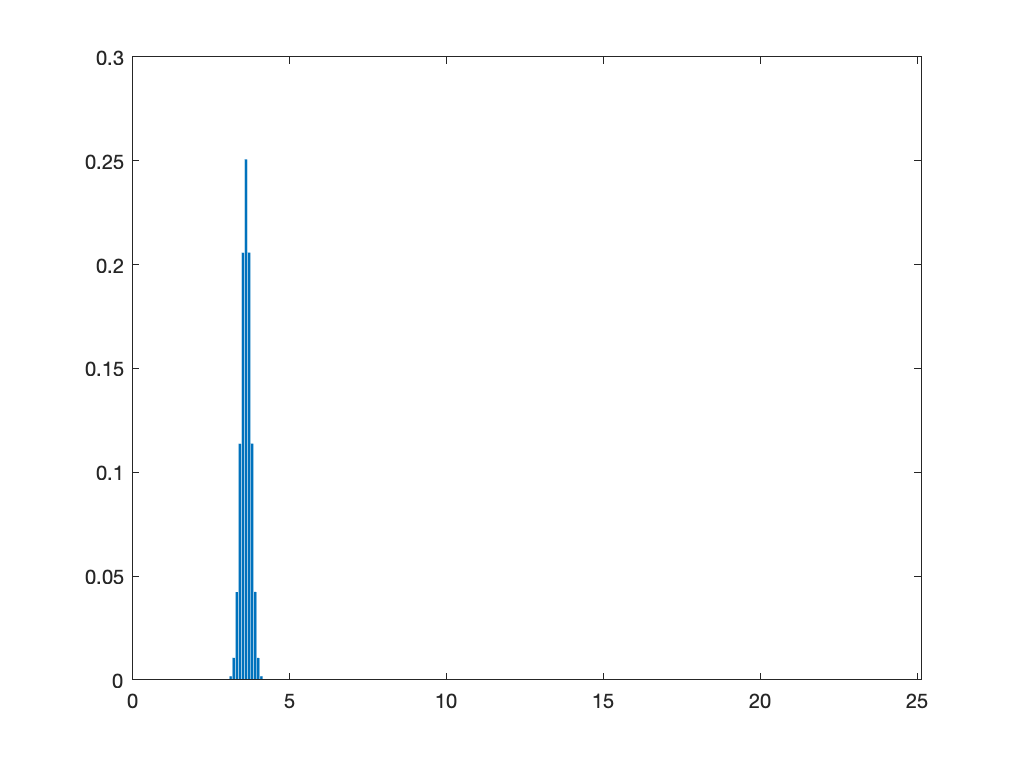

width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));


Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
bar(x,Gaussian_y)


Gaussian_y=Gaussian_y';

load('prf_good.mat')

Error using load
Unable to find file or directory 'prf_good.mat'.

Gaussian_y1 = prf;
peak=find(Gaussian_y1==max(Gaussian_y1))
x_i=(1:1:256)-peak;
x=x_i*(25/256);
figure
bar(x,Gaussian_y1)

load('prf_bad.mat')
Gaussian_y2 = prf;
peak=find(Gaussian_y2==max(Gaussian_y2))

peak = 38

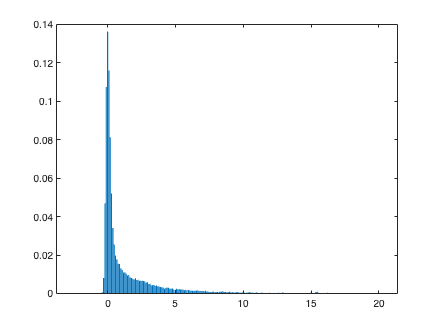

x_i=(1:1:256)-peak;
x=x_i*(25/256);
figure
bar(x,Gaussian_y2)

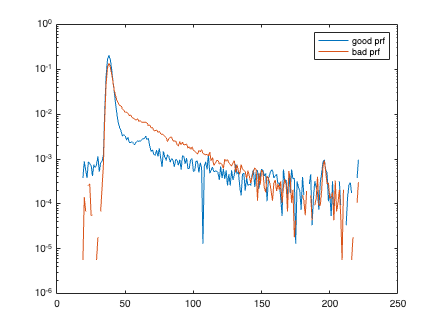


figure
semilogy(Gaussian_y1)
hold on
semilogy(Gaussian_y2)

legend('good prf','bad prf')

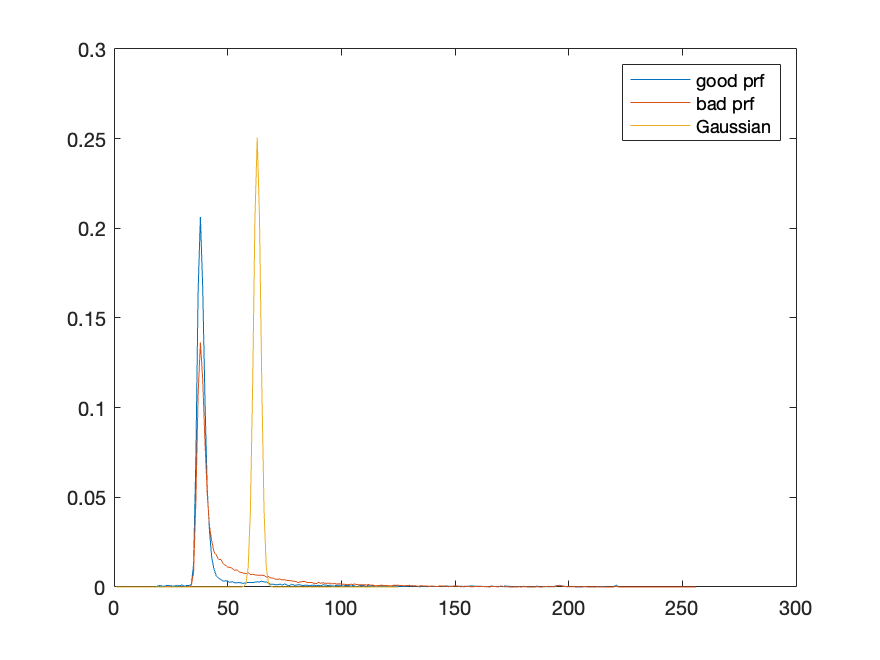


figure
plot(Gaussian_y1)
hold on
plot(Gaussian_y2)
hold on
plot(Gaussian_y)
legend('good prf','bad prf','Gaussian')


a_conv_1=[];

for i=1:1000
    a=find(histc(rand(),[cumsum(Gaussian_y(:))]));
   % whether this line of code is correct: use uniformly distritubted
   % number between [0 1] instead of rand();
   % plot the numbers from rand() function;
    a_conv_1=[a_conv_1 a];
end

figure
hist(a_conv_1)

a_conv_2=[];

for i=1:100000
    a=find(histc(rand(),[cumsum(Gaussian_y(:))]));
    a_conv_2=[a_conv_2 a];
end

figure
hist(a_conv_2)

a_conv_3=[];

for i=1:10000000
    a=find(histc(rand(),[cumsum(Gaussian_y(:))]));
    a_conv_3=[a_conv_3 a];
end

figure
hist(a_conv_3)


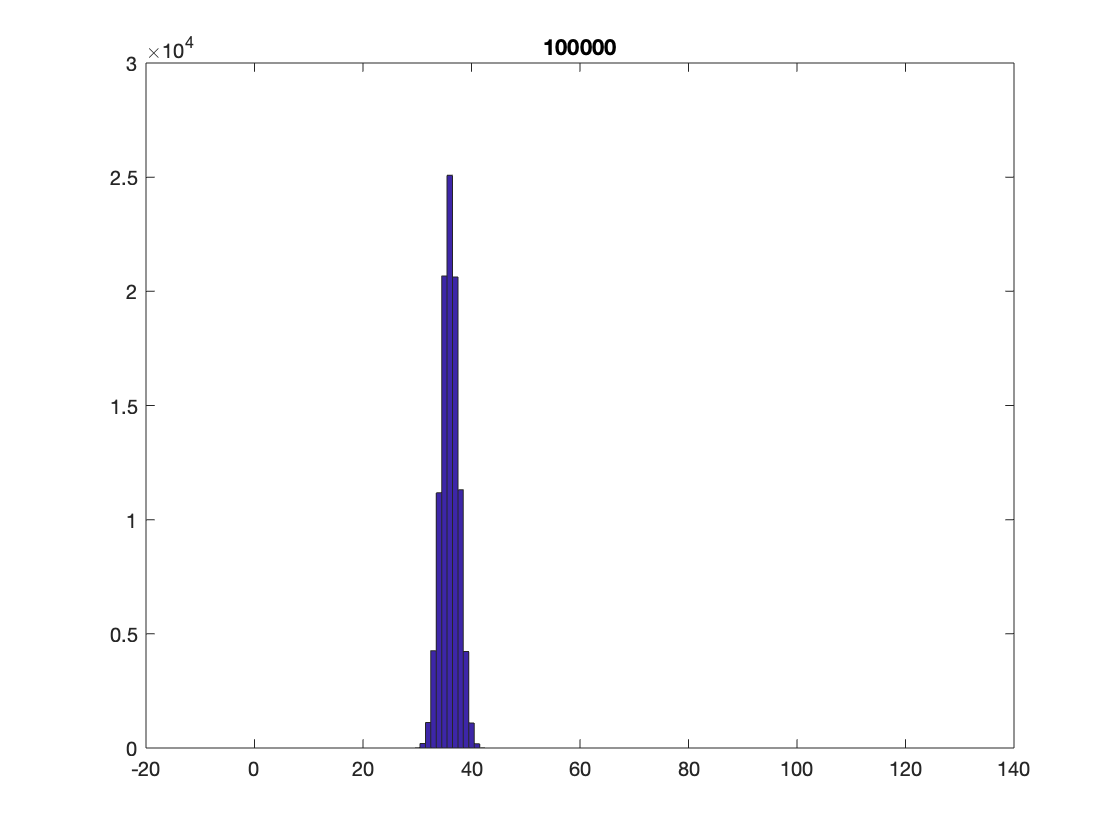

% 
% a_conv_1=[];
% b_1=[];

% 
% for i=1:1000
%     b=rand();
%     b_1=[b_1 b];
%     a=find(histc(b,[cumsum(Gaussian_y(:))]));
%     a_conv_1=[a_conv_1 a];
% end

% figure
% hist(a_conv_1,0:1:124)
% title('1000')

% a_conv_2=[];
% b_2=[];
% 
% for i=1:100000
%     b=rand();
%     b_2=[b_2 b];
%     a=find(histc(b,[cumsum(Gaussian_y(:))]));
%     a_conv_2=[a_conv_2 a];
% end

figure
hist(a_conv_2,0:1:125);
title('100000')


% a_conv_3=[];
% b_3=[];
% 
% for i=1:1000000
%     b=rand();
%     b_3=[b_3 b];
%     a=find(histc(b,[cumsum(Gaussian_y(:))]));
%     a_conv_3=[a_conv_3 a]
% end

% figure
% [n_3,bins_3]=hist(a_conv_3,0:1:124)
% title('1000000')


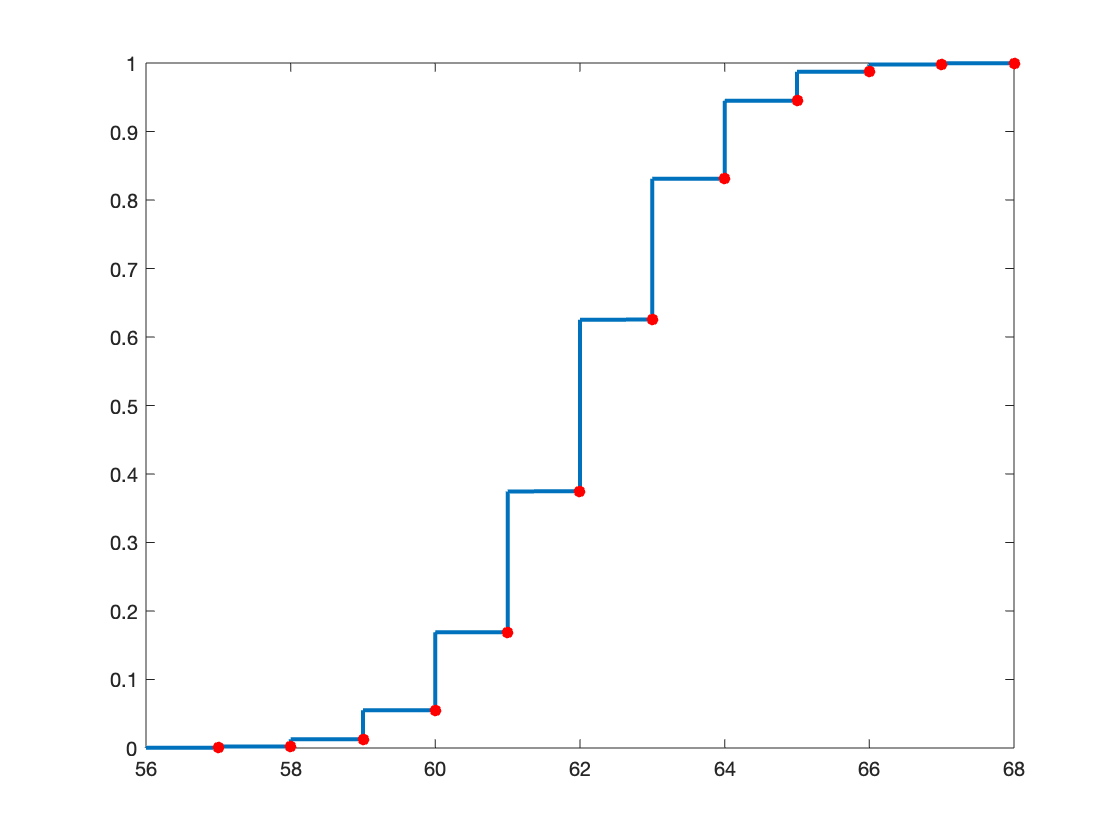

test=0.0001:0.0001:0.9999;
c_all=[];
test_transit=[];
c_transit=[];

for i=1:length(test)
    c=find(histc(test(i),[cumsum(Gaussian_y(:))]));
    c_all=[c_all c];
    if i>1 & c_all(i)-c_all(i-1)>0
        test_transit=[test_transit test(i)];
        c_transit=[c_transit c];
    end
end

figure
plot(c_all, test,'lineWidth',2)
hold on
scatter(c_transit,test_transit,'filled','red')


[n,xout]=hist(c_all,0:1:130)

n =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


xout =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


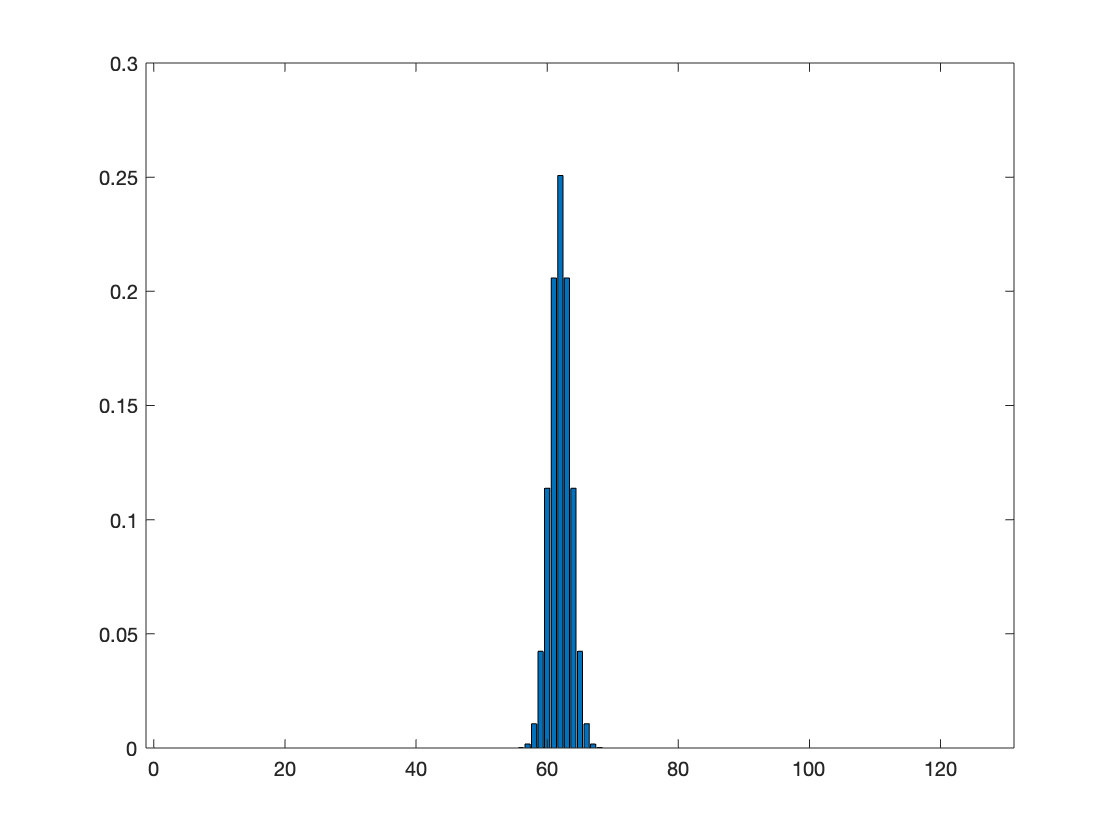

figure
bar(xout,n/sum(n))

c=linspace(0,1,100)

c =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


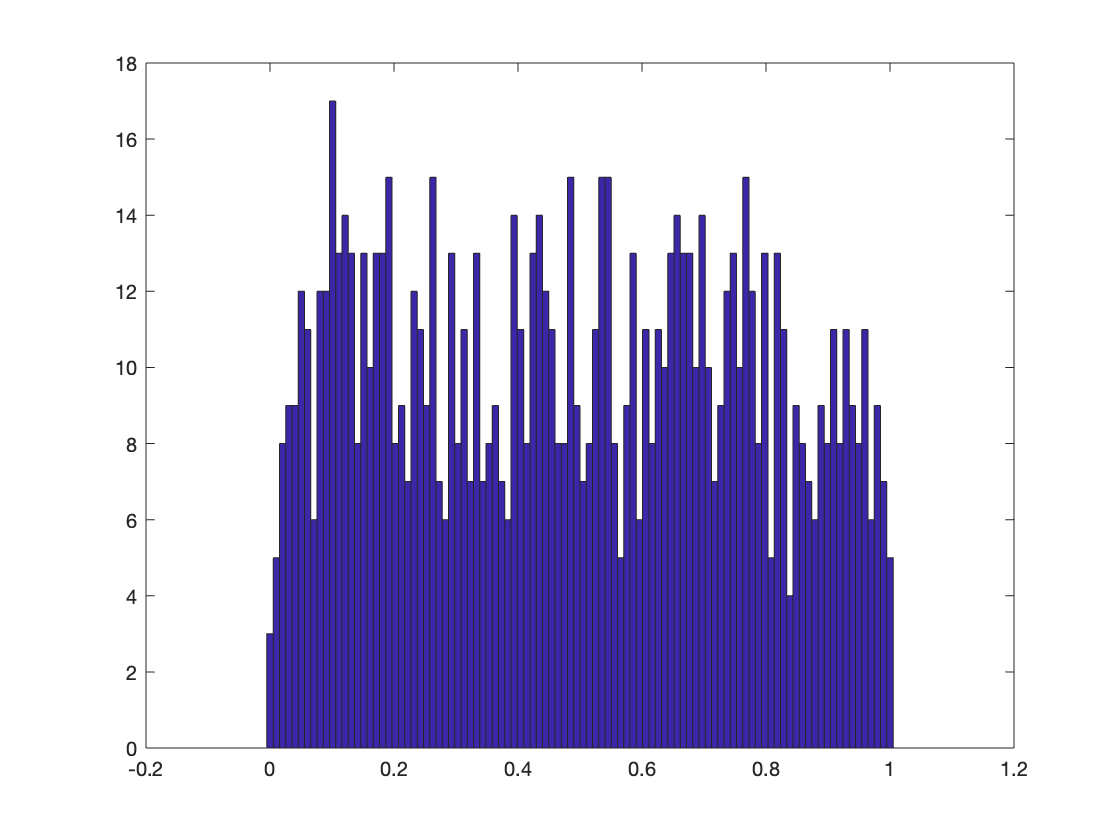

figure
hist(b_1,c)

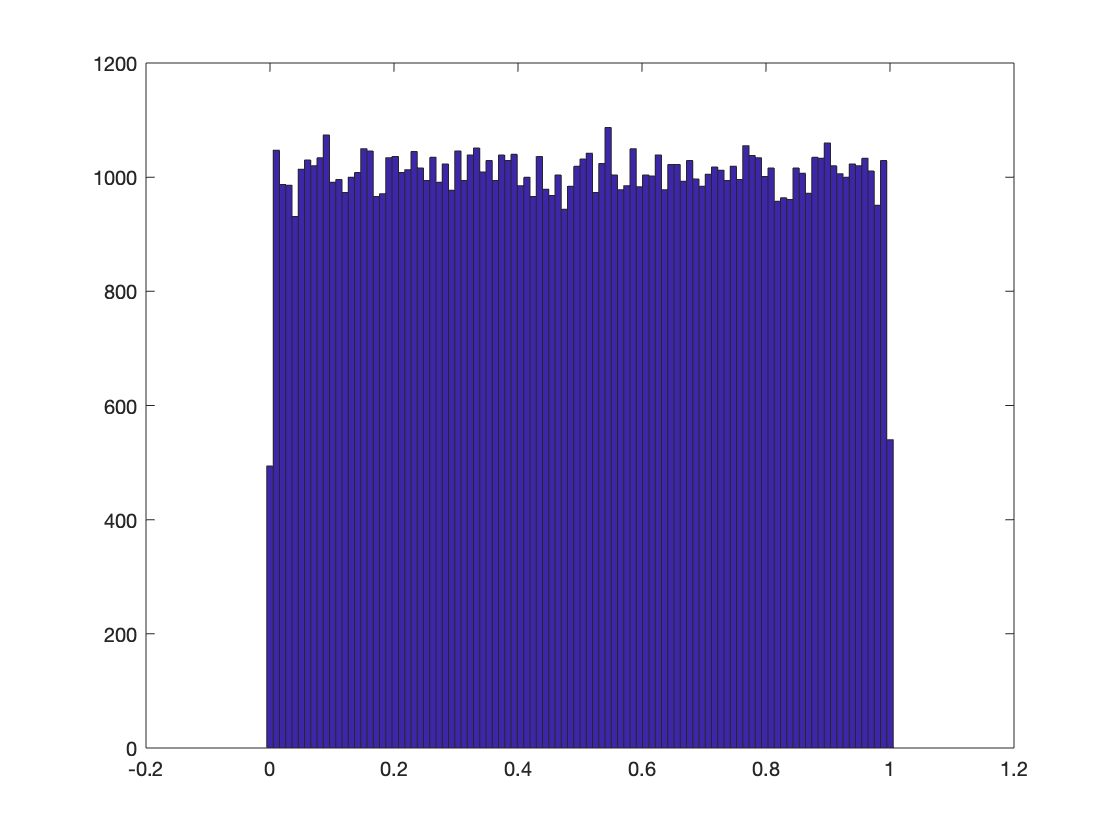


figure
hist(b_2,c)

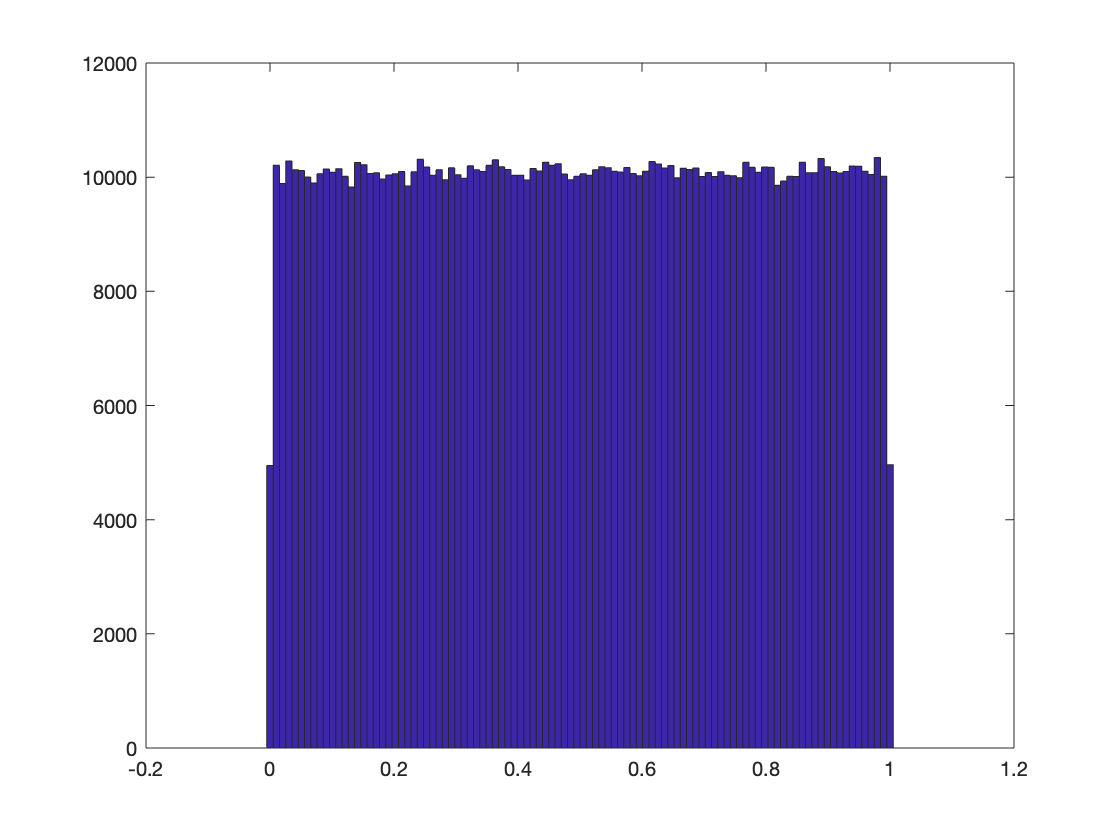


figure
hist(b_3,c)

TP_s=[1000 2000 3000 4000 6000 7000 8000 9000 10000 11000 12000 13000 14000 15000 16000];
tau1=2.706;
p1=0.8;
tau2=0.2613;
p2=0.2;
peaks=[];
photons=[];
xsim=linspace(0,25,256);
x_i=(1:1:256)-peak;
x=x_i*(25/256);

for k=1:15
    TP=TP_s(k);
    PopulationName=num2str(TP);
%     GenPop256_FLP(TP, p1, p2, tau1, tau2, PopulationName);
    load(PopulationName)
    photons=[photons length(Population)];
    [n,xout]=hist(Population, xsim);
    
    
    for i=1:256
        eval(['n_c_',num2str(i),'=zeros(1,256);'])
        n_i = n(i)*Gaussian_y1';
        x_c=x_i+i; 
        
        for j=1:size(x_c,2)
            if x_c(j)<=0
               x_c(j)=x_c(j)+256;  
            end
            
            if x_c(j)>256
                x_c(j)=x_c(j)-256;
            end
            
        end
        eval(['n_c_',num2str(i),'(x_c)=n_c_',num2str(i),'(x_c)+n_i;'])
%         n_c(x_c)=n_c(x_c)+n_i;
    end
    figure
    
    for i=1:256
        eval(['plot(n_c_',num2str(i),')'])
        hold on
    end
    plot(n,'LineWidth',2,'Color','g')
    hold on
    
    n_c=zeros(1,256);
    for i=1:256
        eval(['this_n=n_c_',num2str(i),';'])
        n_c=[n_c;this_n];
    end
    n_c_all=sum(n_c);
    eval(['hist_prf1_',num2str(k),'=n_c_all;'])
    
    plot(n_c_all,'LineWidth',2,'Color','r');
    hold off
    peaks=[peaks find(n_c_all==max(n_c_all))];
end

Unrecognized function or variable 'Gaussian_y1'.

    
photons
peaks

figure
plot(photons,peaks)

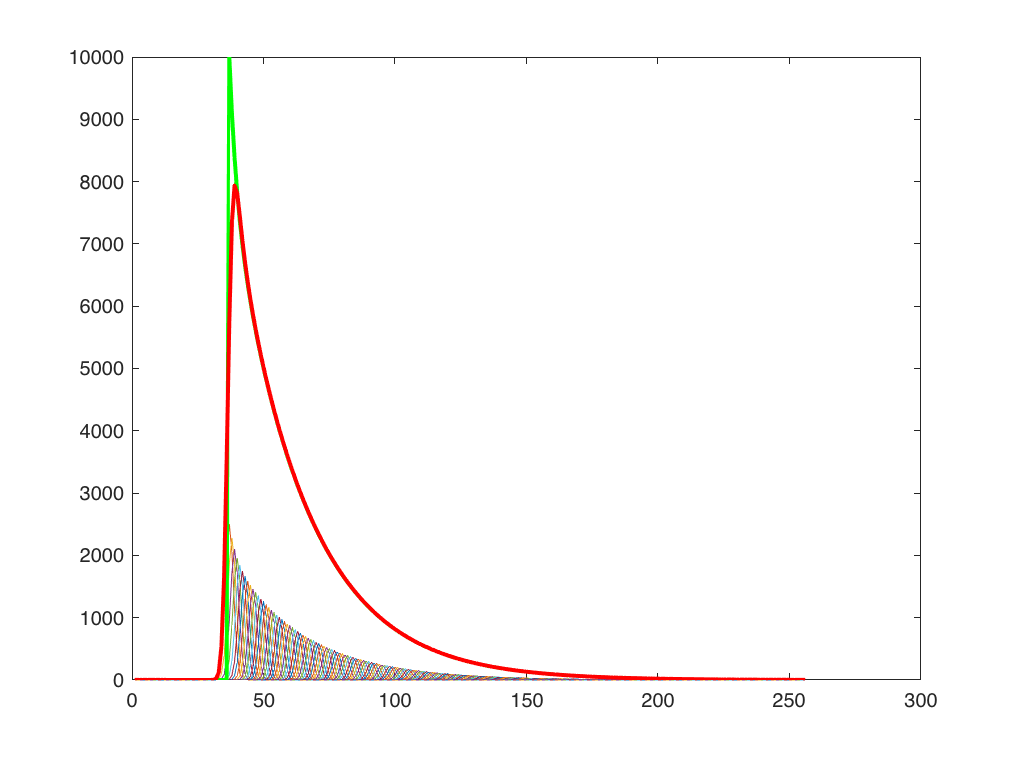

TP_s=[1000 2000 3000 4000 6000 7000 8000 9000 10000 11000 12000 13000 14000 15000 16000];
tau1=2.706;
p1=0.8;
tau2=0.2613;
p2=0.2;
peaks=[];
photons=[];
xsim=linspace(0,25,256);
x_i=(1:1:256)-peak;
x=x_i*(25/256);

for k=9%1:15
    TP=TP_s(k);
    PopulationName=num2str(TP);
    GenPop256_FLP(TP, p1, p2, tau1, tau2, PopulationName);
    load(PopulationName)
    photons=[photons length(Population)];
    [n,xout]=hist(Population, xsim);
    
    
    for i=1:256
        eval(['n_c_',num2str(i),'=zeros(1,256);'])
        n_i = n(i)*Gaussian_y';
        x_c=x_i+i; 
        
        for j=1:size(x_c,2)
            if x_c(j)<=0
               x_c(j)=x_c(j)+256;  
            end
            
            if x_c(j)>256
                x_c(j)=x_c(j)-256;
            end
            
        end
        eval(['n_c_',num2str(i),'(x_c)=n_c_',num2str(i),'(x_c)+n_i;'])
%         n_c(x_c)=n_c(x_c)+n_i;
    end
    figure
    xlabel('Channels')
    ylabel('Photon Count')
    for i=1:256
        eval(['plot(n_c_',num2str(i),')'])
        hold on
    end
    plot(n,'LineWidth',2,'Color','g')
    hold on
    
    n_c=zeros(1,256);
    for i=1:256
        eval(['this_n=n_c_',num2str(i),';'])
        n_c=[n_c;this_n];
    end
    n_c_all=sum(n_c);
    eval(['hist_prf2_',num2str(k),'=n_c_all;'])
    
    plot(n_c_all,'LineWidth',2,'Color','r');
    hold off
    peaks=[peaks find(n_c_all==max(n_c_all))];
end

    
photons

photons =       231079


peaks

peaks =     39


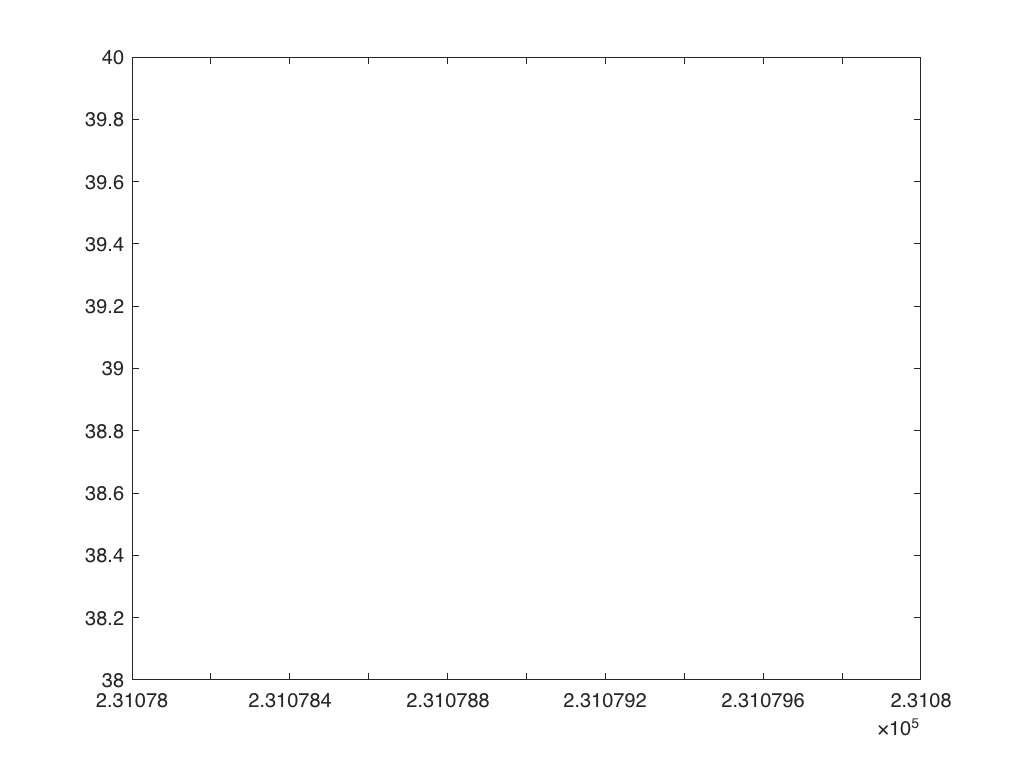


figure
plot(photons,peaks)

TP_s=[1000 2000 3000 4000 6000 7000 8000 9000 10000 11000 12000 13000 14000 15000 16000];
tau1=2.706;
p1=0.2;
tau2=0.2613;
p2=0.8;
peaks=[];
photons=[];
xsim=linspace(0,25,256);
x_i=-62:1:62;
x=x_i*(25/256);

for k=9%1:15
    TP=TP_s(k);
    PopulationName=num2str(TP);
%     GenPop256_FLP(TP, p1, p2, tau1, tau2, PopulationName);
    load(PopulationName)
    photons=[photons length(Population)];
    [n,xout]=hist(Population, xsim);
    
    
    for i=1:256
        eval(['n_c_',num2str(i),'=zeros(1,256);'])
        n_i = n(i)*Gaussian_y';
        x_c=x_i+i;
        
        for j=1:size(x_c,2)
            if x_c(j)<=0
               x_c(j)=x_c(j)+256;  
            end
            
            if x_c(j)>256
                x_c(j)=x_c(j)-256;
            end
            
        end
        eval(['n_c_',num2str(i),'(x_c)=n_c_',num2str(i),'(x_c)+n_i;'])
%         n_c(x_c)=n_c(x_c)+n_i;
    end
    figure
    
    for i=1:256
        eval(['plot(n_c_',num2str(i),')'])
        hold on
    end
    plot(n,'LineWidth',2,'Color','g')
    hold on
    
    n_c=zeros(1,256);
    for i=1:256
        eval(['this_n=n_c_',num2str(i),';'])
        n_c=[n_c;this_n];
    end
    n_c_all=sum(n_c);
    eval(['hist_gau_',num2str(k),'=n_c_all;'])
    
    
    plot(n_c_all,'LineWidth',2,'Color','r');
    hold off
    peaks=[peaks find(n_c_all==max(n_c_all))];
end

Arrays have incompatible sizes for this operation.

Related documentation

    
photons
peaks

figure
plot(photons,peaks)


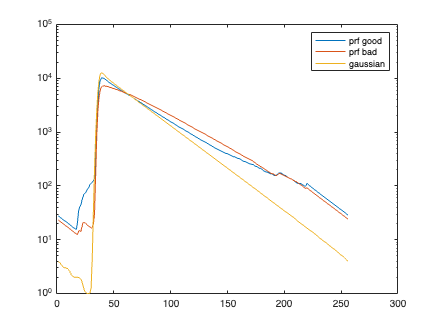

figure
semilogy(hist_prf1_15)
hold on
semilogy(hist_prf2_15)
hold on
semilogy(hist_gau_15)
legend('prf good','prf bad','gaussian')

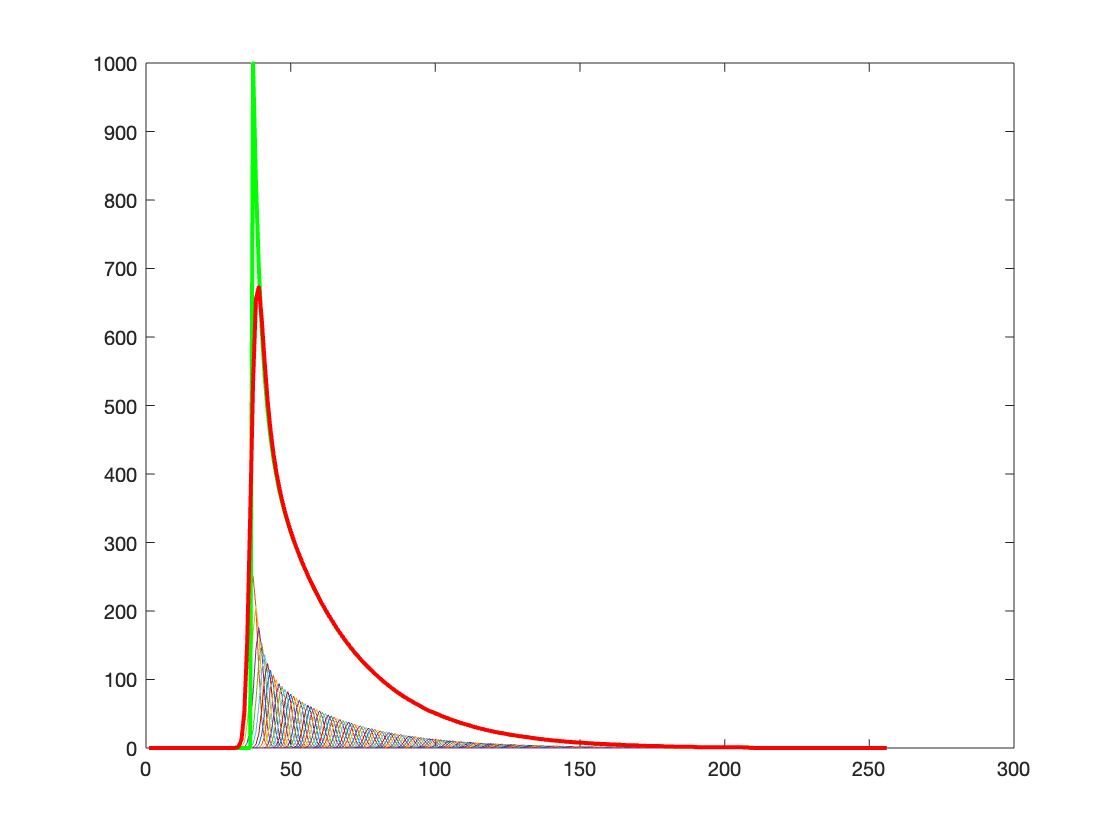

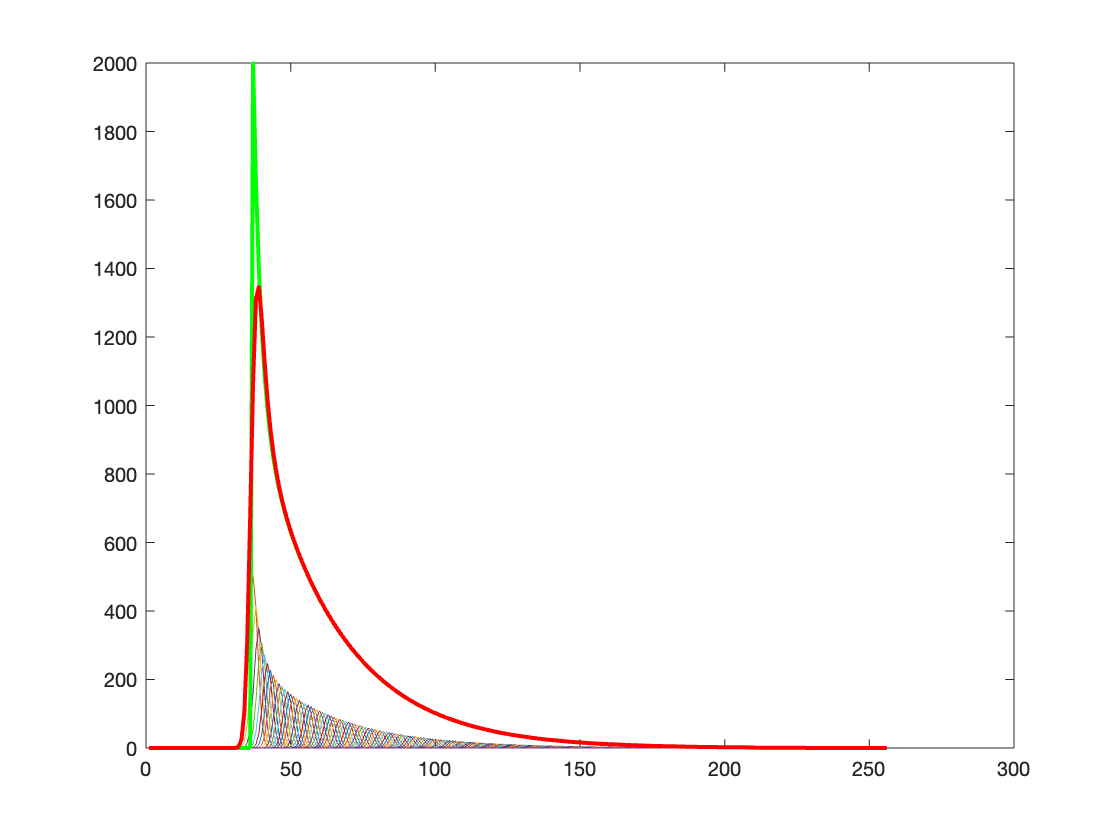

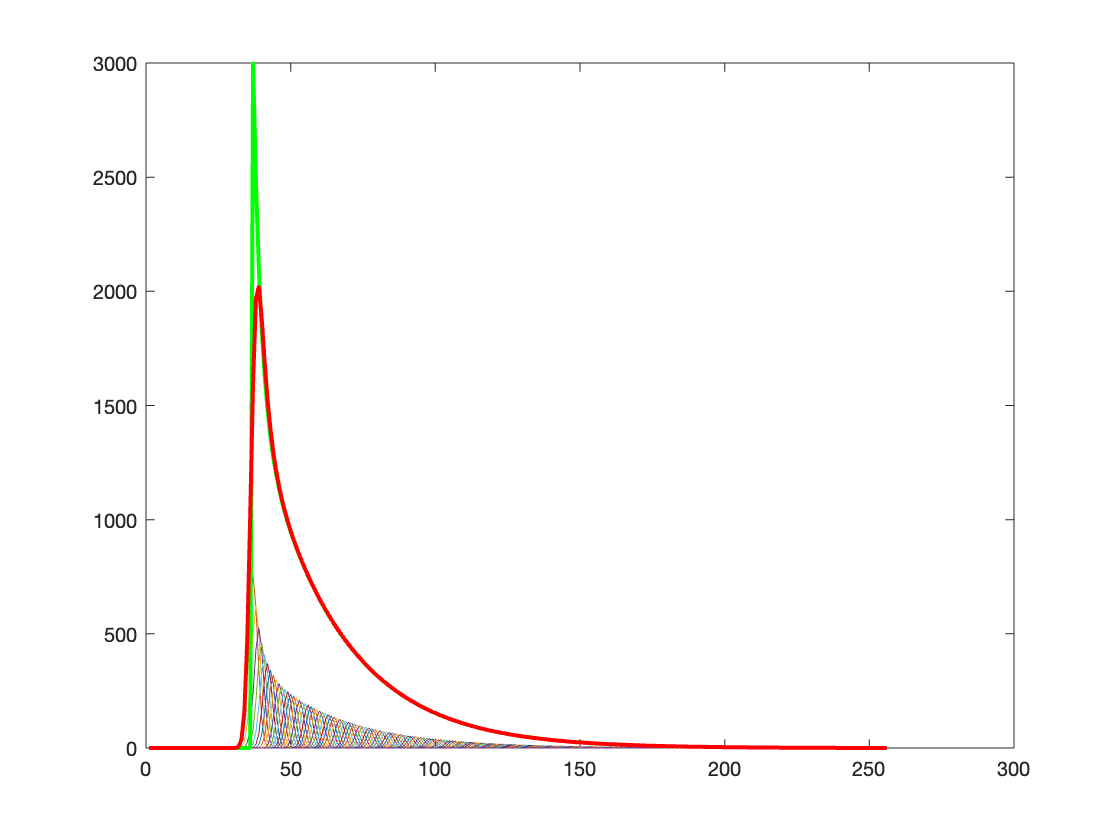

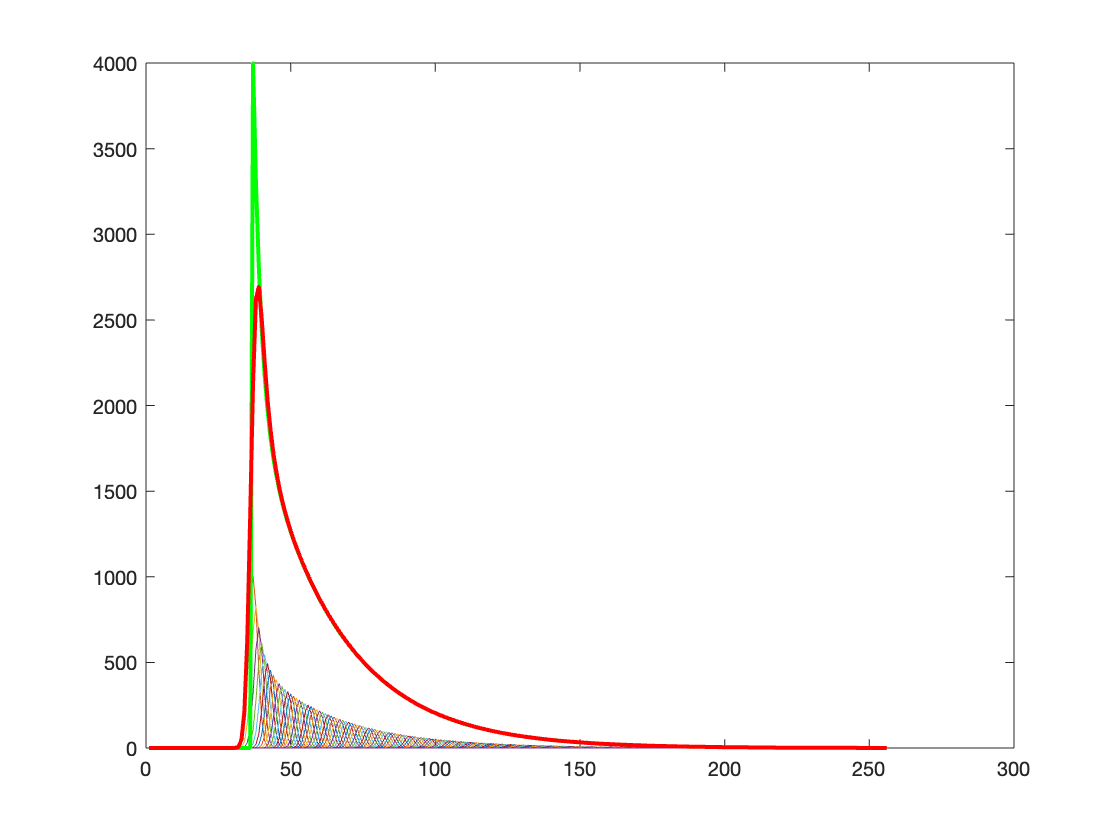

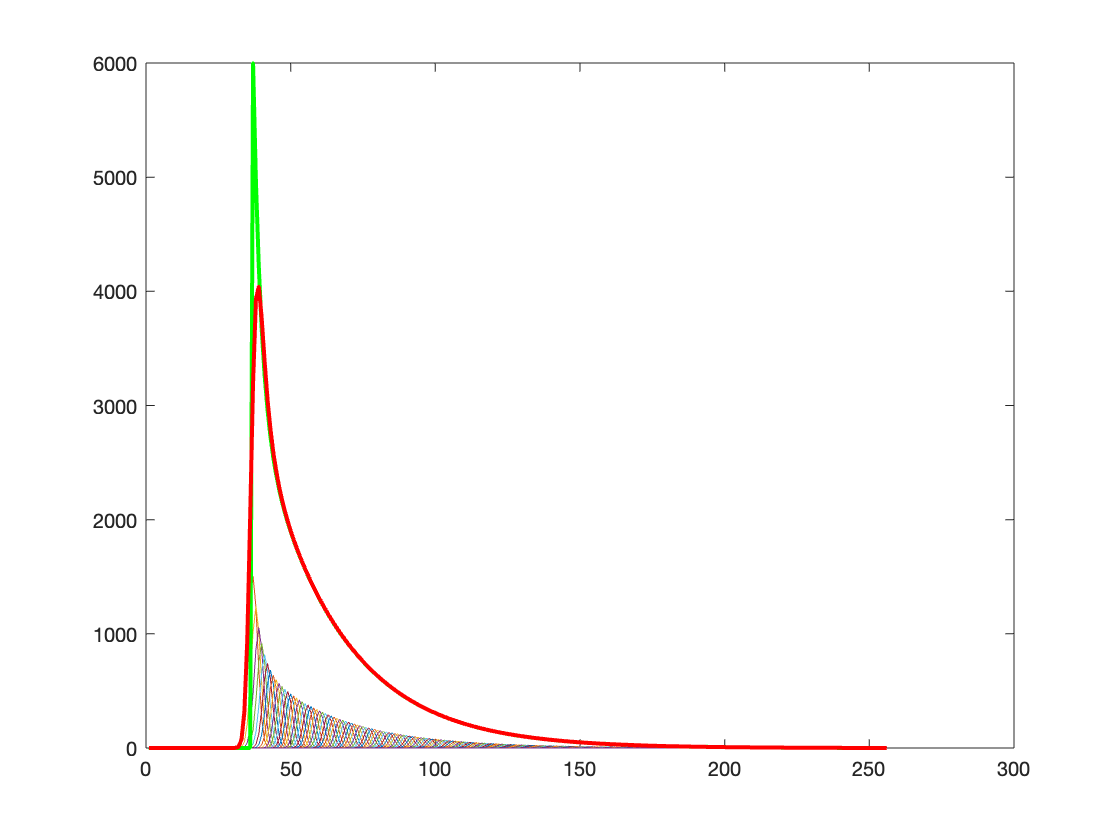

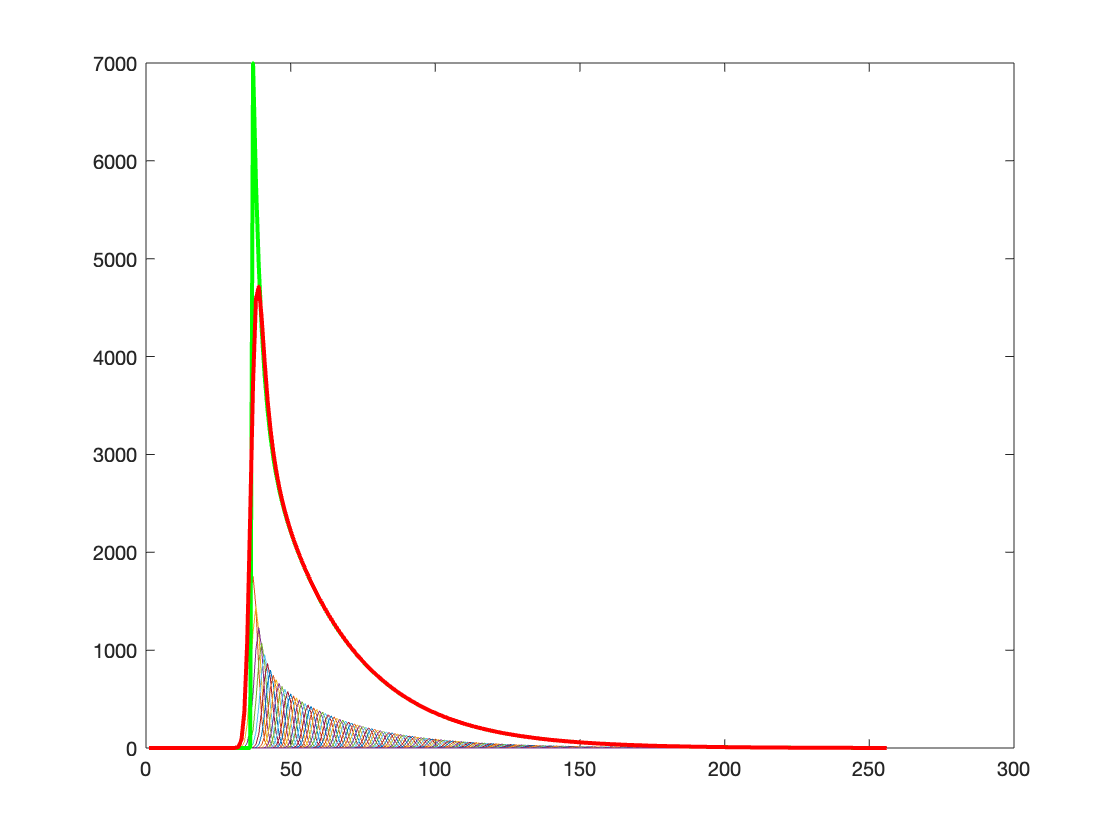

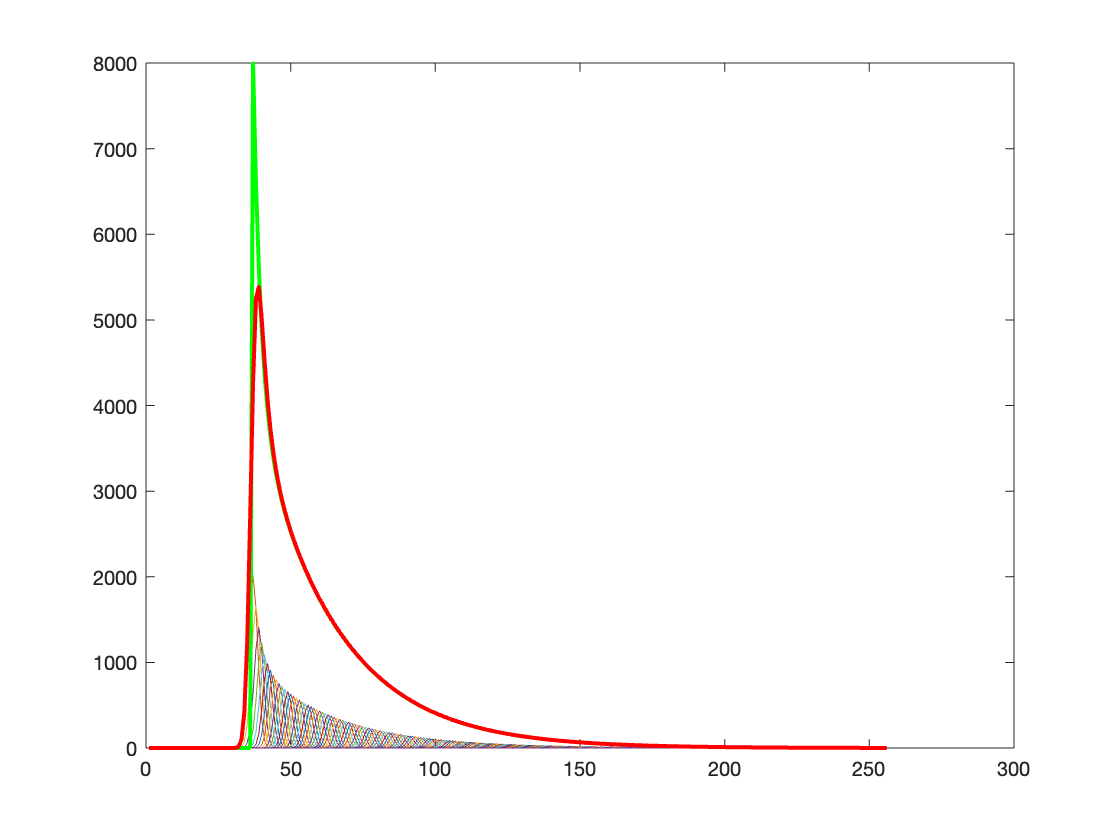

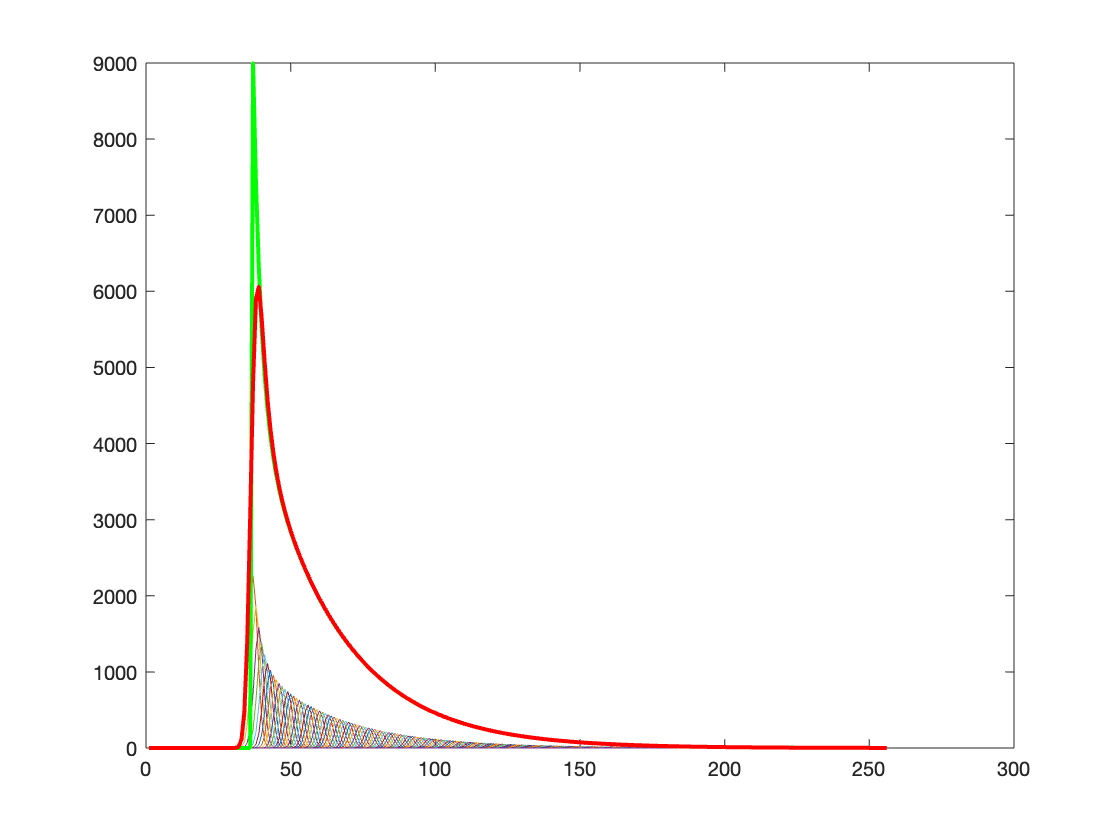

TP_s=[1000 2000 3000 4000 6000 7000 8000 9000 10000 11000 12000 13000 14000 15000 16000];
tau1=2.706;
p1=0.5;
tau2=0.2613;
p2=0.5;
peaks=[];
photons=[];

for k=1:15
    TP=TP_s(k);
    PopulationName=num2str(TP);
    GenPop256_FLP(TP, p1, p2, tau1, tau2, PopulationName);
    load(PopulationName)
    photons=[photons length(Population)];
    [n,xout]=hist(Population, xsim);
    
    
    for i=1:256
        eval(['n_c_',num2str(i),'=zeros(1,256);'])
        n_i = n(i)*Gaussian_y;
        x_c=x_i+i;
        
        for j=1:size(x_c,2)
            if x_c(j)<=0
               x_c(j)=x_c(j)+256;  
            end
            
            if x_c(j)>256
                x_c(j)=x_c(j)-256;
            end
            
        end
        eval(['n_c_',num2str(i),'(x_c)=n_c_',num2str(i),'(x_c)+n_i;'])
%         n_c(x_c)=n_c(x_c)+n_i;
    end
    figure
    
    for i=1:256
        eval(['plot(n_c_',num2str(i),')'])
        hold on
    end
    plot(n,'LineWidth',2,'Color','g')
    hold on
    
    n_c=zeros(1,256);
    for i=1:256
        eval(['this_n=n_c_',num2str(i),';'])
        n_c=[n_c;this_n];
    end
    n_c_all=sum(n_c);
    
    
    plot(n_c_all,'LineWidth',2,'Color','r');
    hold off
    peaks=[peaks find(n_c_all==max(n_c_all))];
end

    
photons

photons =        15536       31181       46827       62470       93774      109417      125067      140711      156358      172005      187665      203310      218953      234608      250262


peaks

peaks =     39    39    39    39    39    39    39    39    39    39    39    39    39    39    39


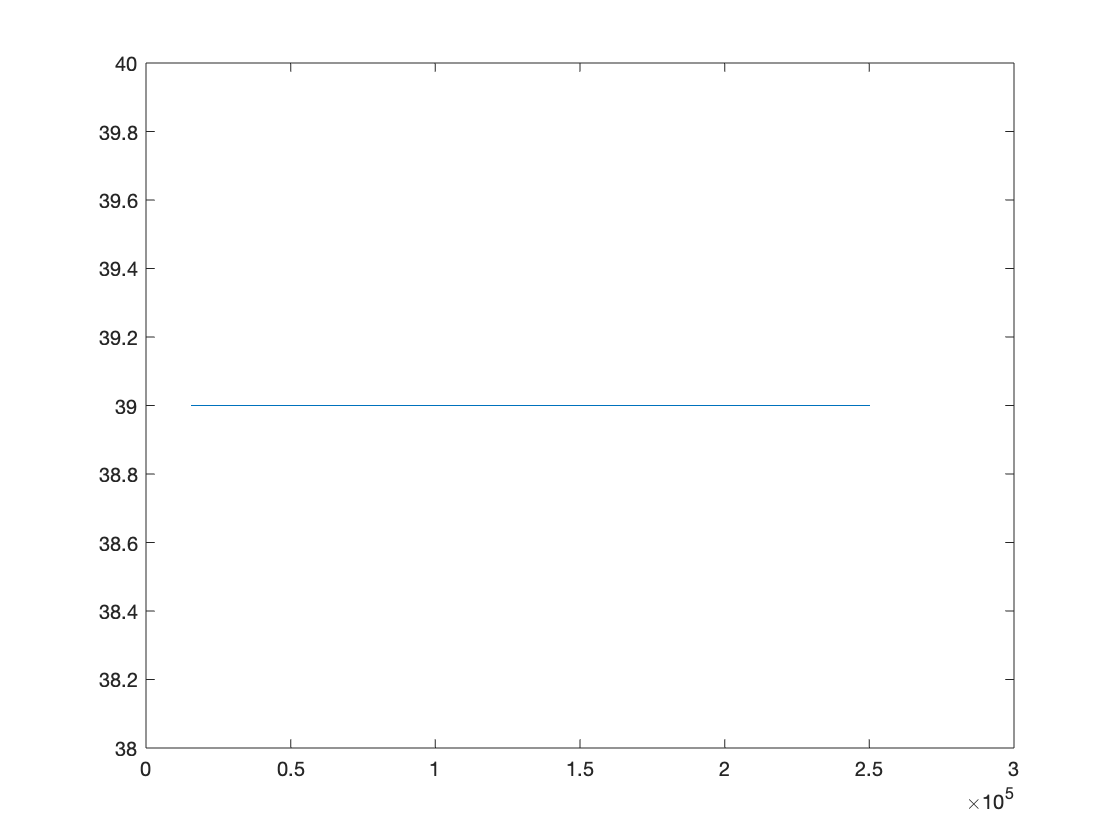


figure
plot(photons,peaks)

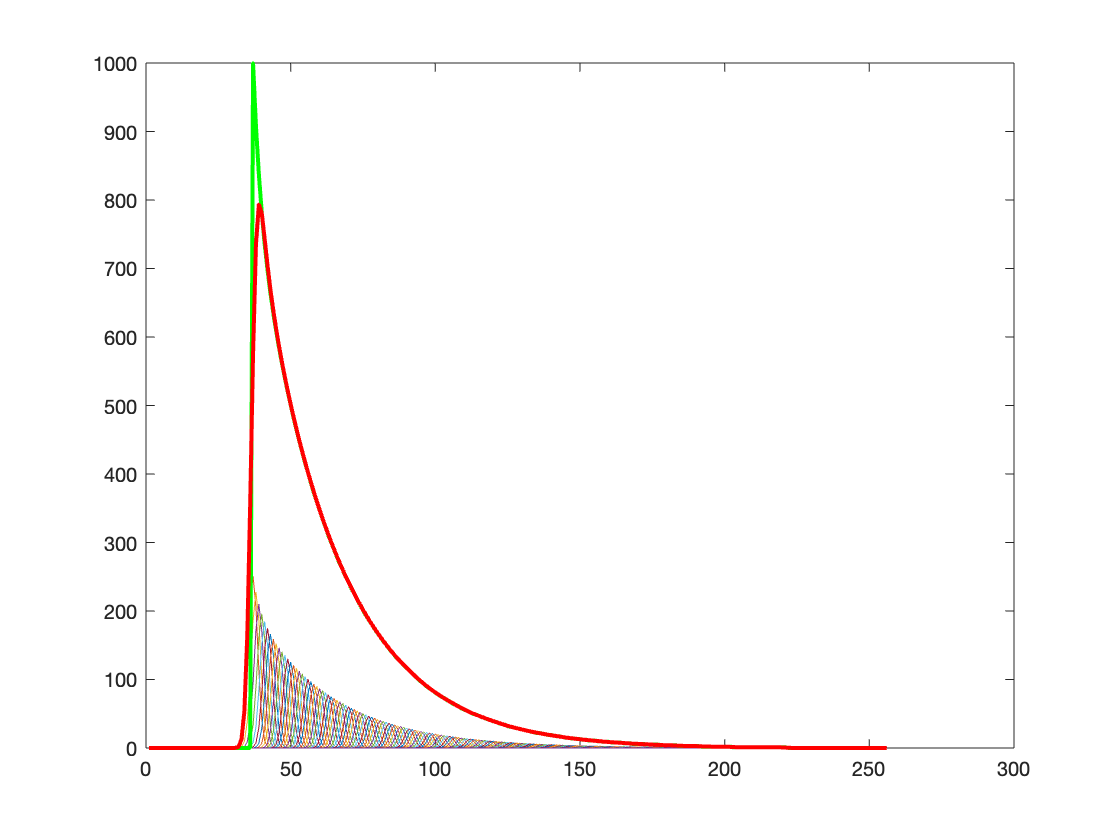

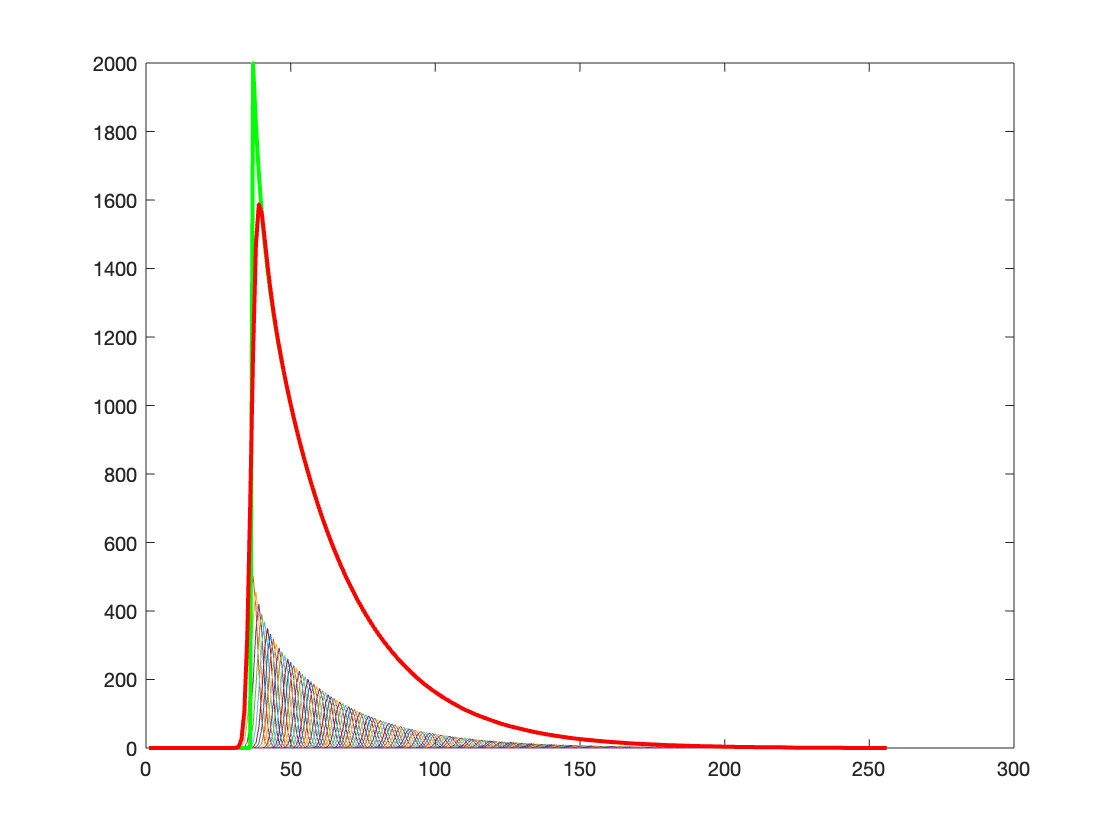

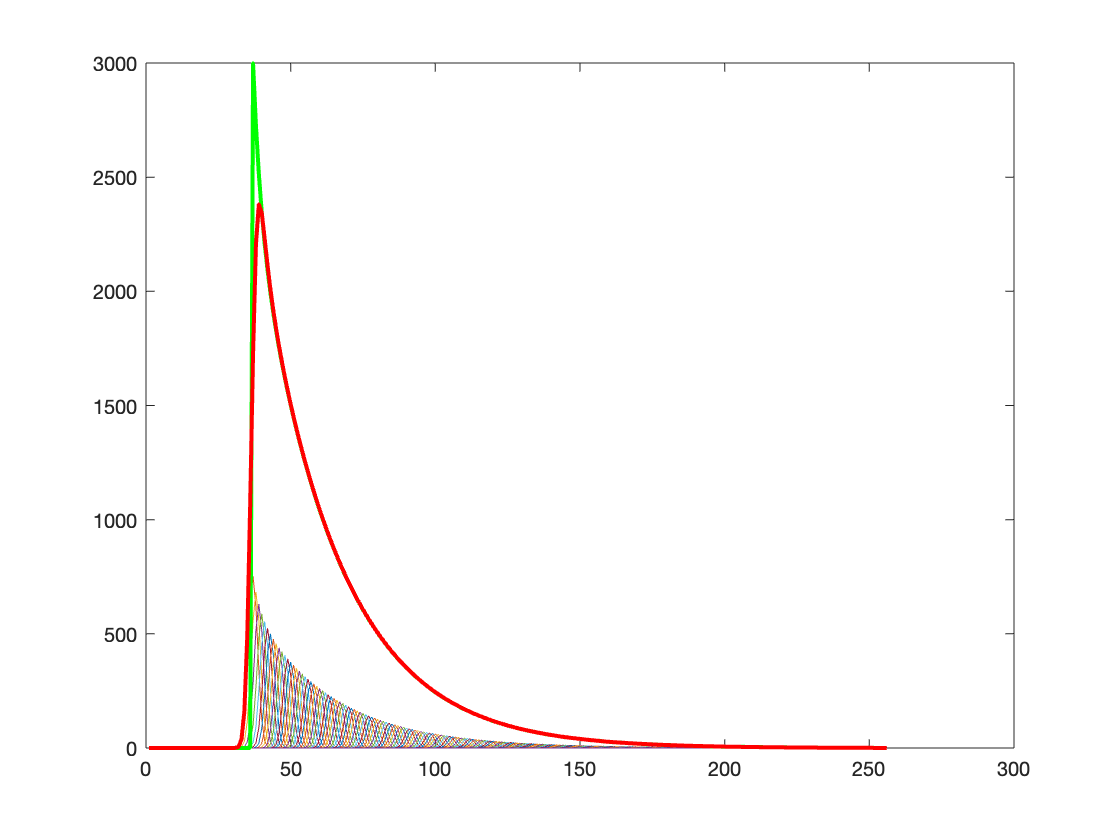

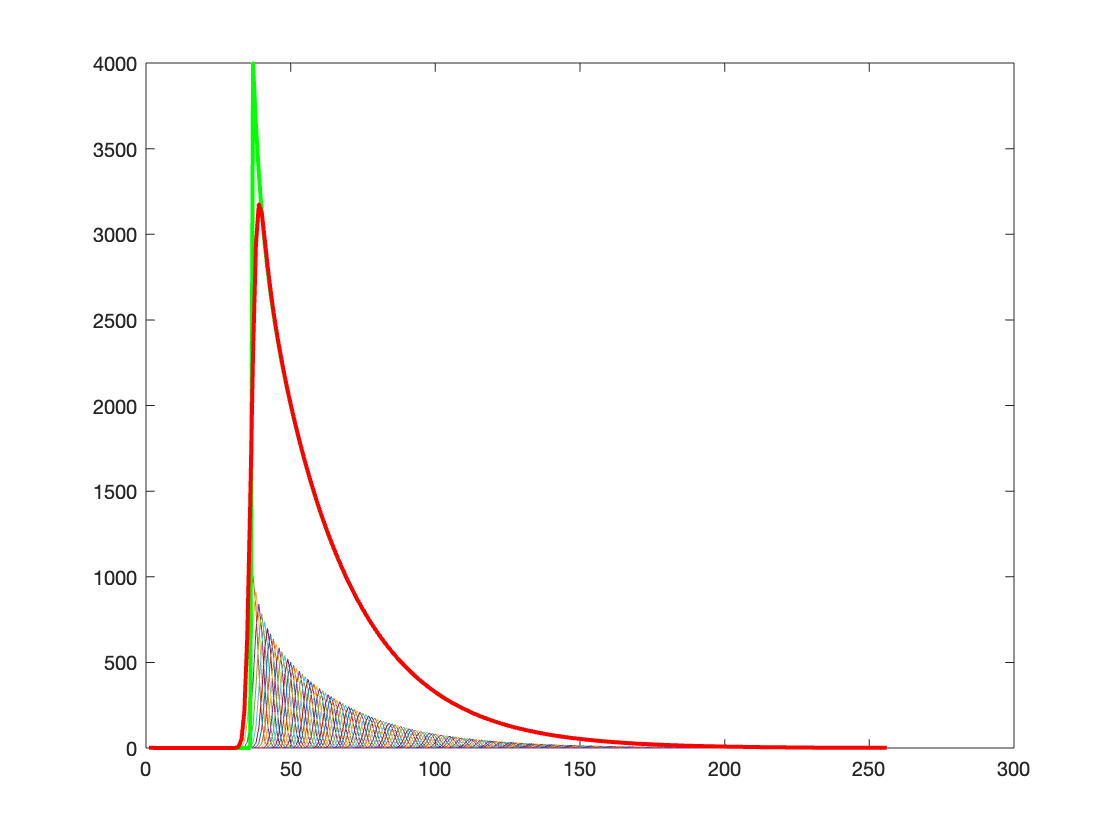

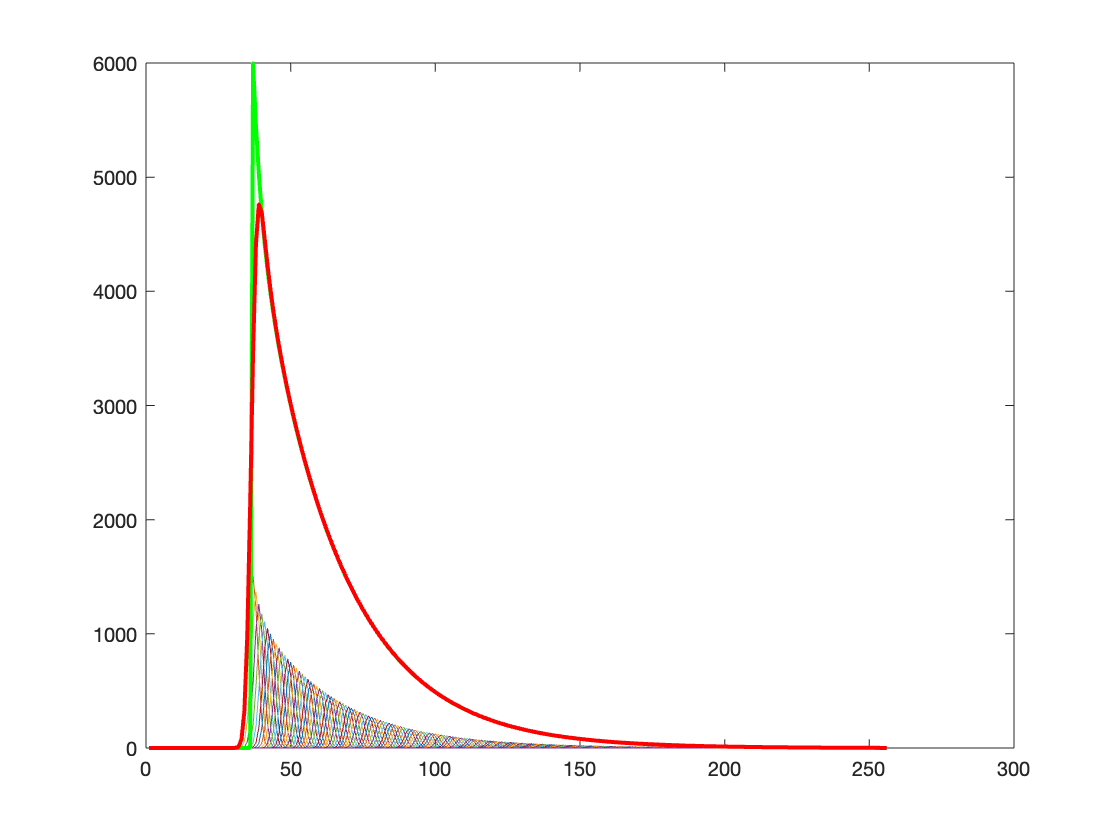

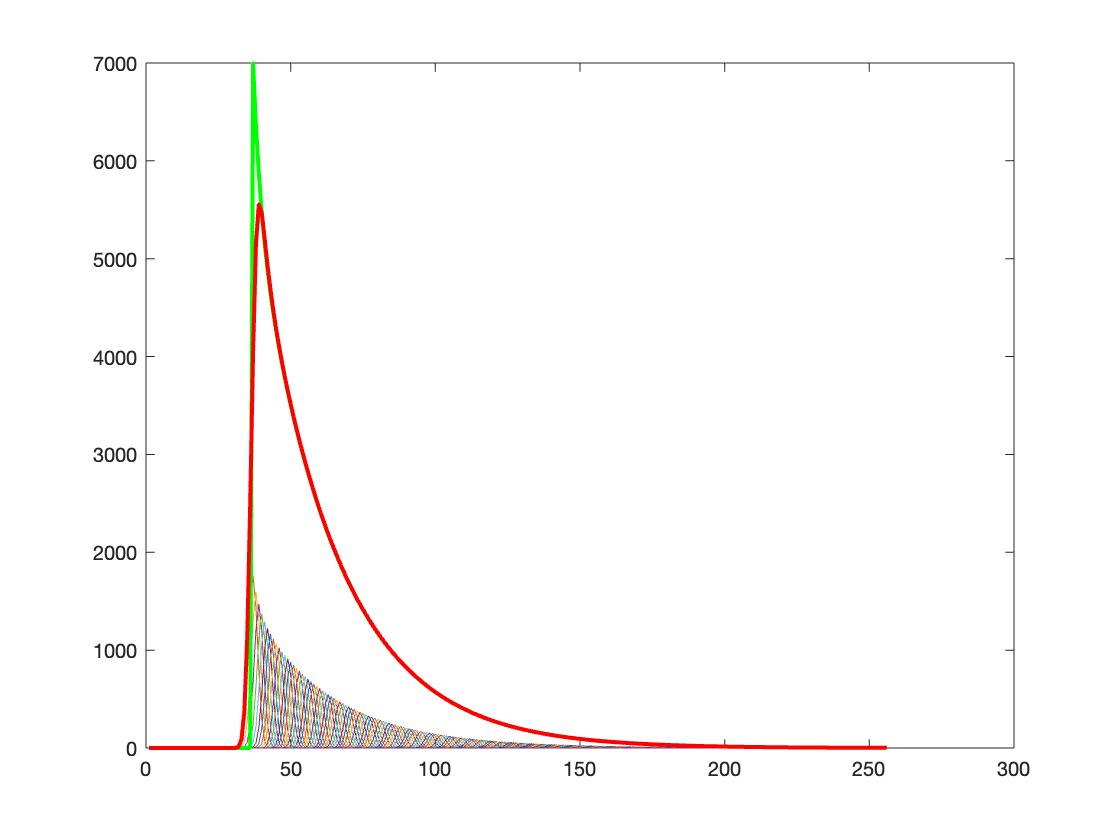

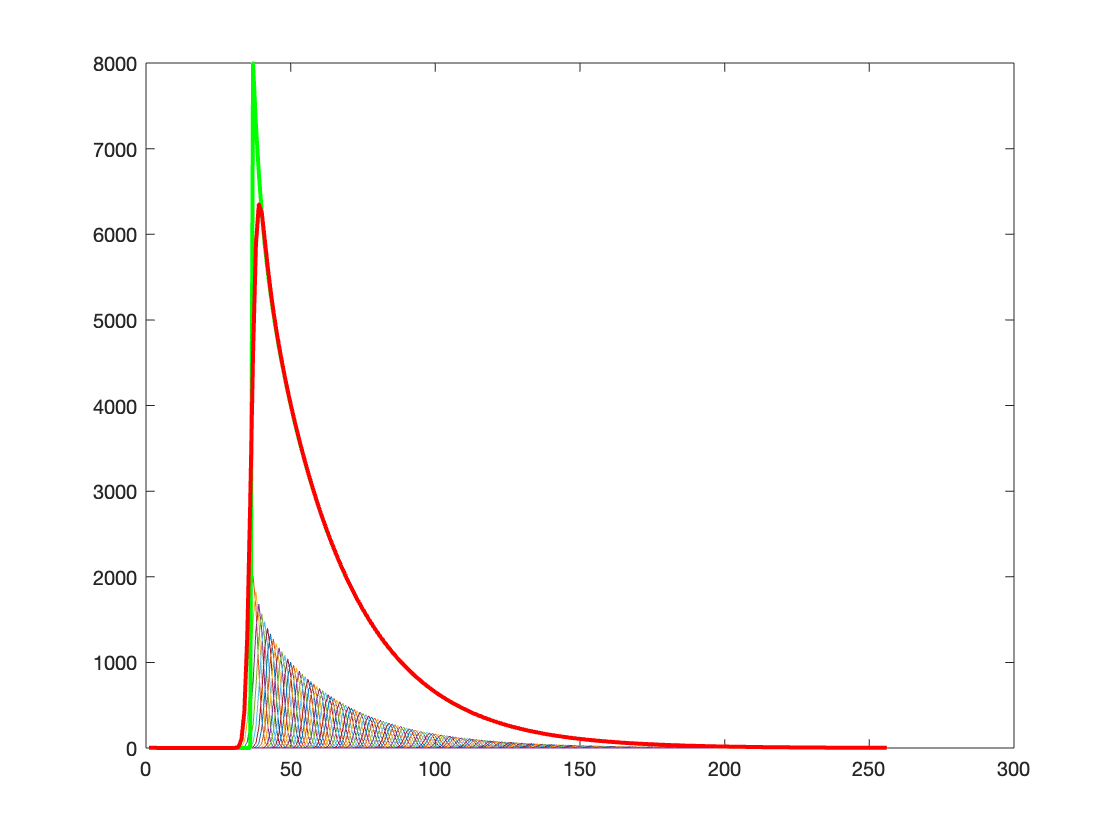

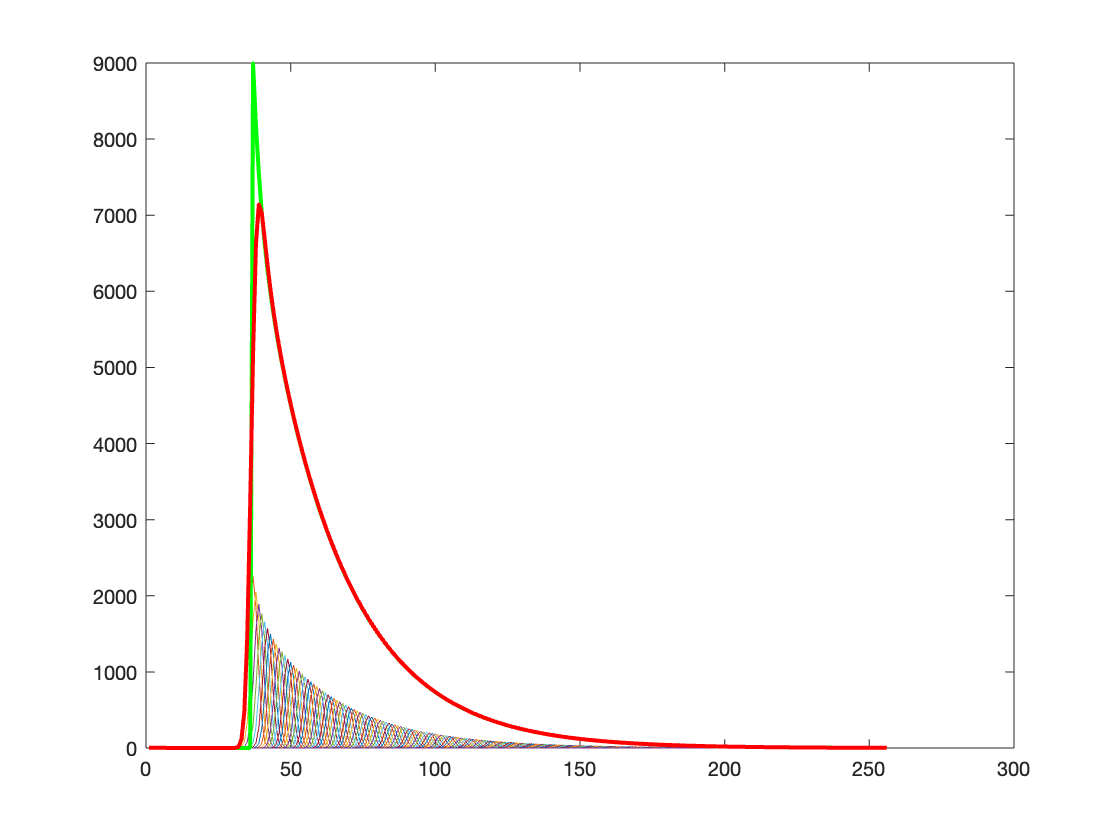

photons =        23003       46120       69240       92354      138593      161713      184831      207957      231079      254198      277322      300443      323561      346687      369803


peaks =     39    39    39    39    39    39    39    39    39    39    39    39    39    39    39